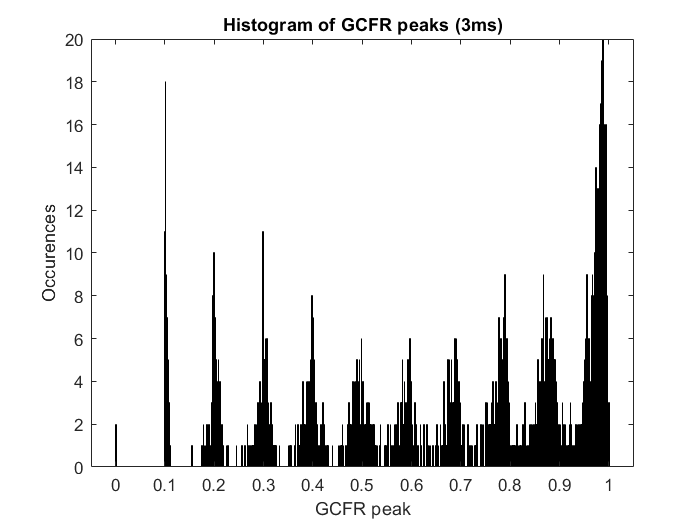

L = 100;
alpha = 4;
gauss_win = gausswin(L, alpha);
fs = 10000;

for i = 2
    start = blwgn(i).OFF_dur * fs;
    stop = (blwgn(i).ON_dur + blwgn(i).OFF_dur)*fs;
    trial_length = blwgn(i).ON_dur;
    t = (0:1/fs: blwgn(i).ON_dur);
    
    stim = blwgn(i).antennal_movement(:,start:stop);
    raster = blwgn(i).raster(:,start:stop);
    gcfr = zeros(size(raster));
    
%     latency = 0.005*fs;
    trials = blwgn(i).complete_trials;
    sum_of_trials = sum(raster,1);
    
    gcfr = (filter(gauss_win, 1, sum_of_trials))/trials;
    [pks_all, locs_all] = findpeaks(gcfr);
    figure;
    histogram(pks_all, 1000);
    title 'Histogram of GCFR peaks (3ms)';
    xlabel 'GCFR peak';
    ylabel 'Occurences';
    
    [pks_lj,locs_lj] = findpeaks(gcfr, 'MinPeakHeight', 0.75*max(gcfr));
    %[pks_all,locs_all] = findpeaks(gcfr, 'MinPeakHeight', 0.5*max(gcfr));
    
      
    common_locs = intersect(locs_lj, locs_all);
    locs_hj = setxor(locs_all, common_locs);

    pks_hj = gcfr(locs_hj);
    
    window = 0.1*fs;
    stsp_lj = NaN(numel(locs_lj),window);
    stsp_hj = NaN(numel(locs_hj),window);
    
    
    
%     for j=1:trials
        for l=1:numel(locs_lj)
            if locs_lj(l)-window >=1
                stsp_lj(l,:) = mean(stim(:,(locs_lj(l)-window+1):locs_lj(l)),1);
                stsp_std_lj(l,:) = std(stim(:,(locs_lj(l)-window+1):locs_lj(l)),1);
            end
        end
        
        for l=1:numel(locs_hj)
            if locs_hj(l)-window >=1
                stsp_hj(l,:) = mean(stim(:,(locs_hj(l)-window+1):locs_hj(l)),1);
                stsp_std_hj(l,:) = std(stim(:,(locs_hj(l)-window+1):locs_hj(l)),1);
            end
        end
%     end
end

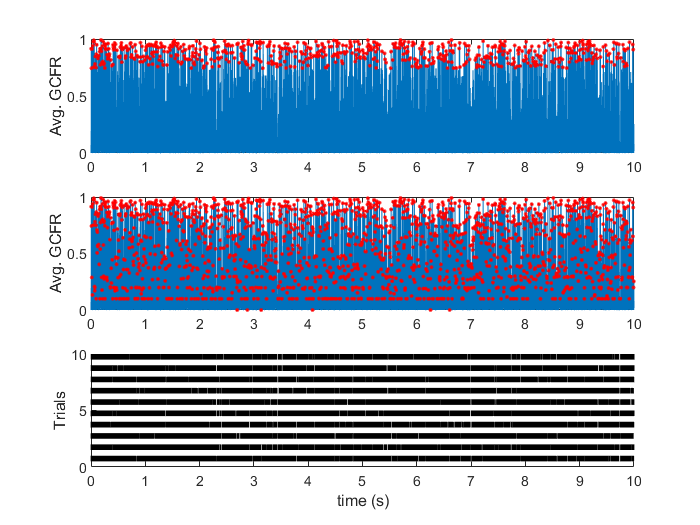

    
    
    figure;
    A1 = subplot(3,1,1); plot(t,gcfr); hold on;
    plot(locs_lj/fs, pks_lj, 'r.');
    ylabel 'Avg. GCFR';
    
%     A2 = subplot(3,1,2); plot(t,gcfr); hold on;
%     plot(locs_hj/fs, pks_hj, 'r.');
%     ylabel 'Avg. GCFR';
    
    A2 = subplot(3,1,2); plot(t,gcfr); hold on;
    plot(locs_all/fs, pks_all, 'r.');
    ylabel 'Avg. GCFR';
        
    A3 = subplot(3,1,3);
    k = 0.5;
    for j = 1:trials
        l = find(raster(j,:)==1);
        spike_time = l/fs;
        for m = 1:length(spike_time)
            line([spike_time(m) spike_time(m)], [k k+0.5], 'Color', 'k', 'LineWidth', 0.01);
        end
        k = k+1;
    end
    
    
    ylabel('Trials');
    xlabel 'time (s)';
    
    linkaxes ([A1 A2 A3], 'x');

nanIndices = any(isnan(stsp_lj),2);
stsp_lj(nanIndices,:) = [];
pks_lj(nanIndices) = [];
stsp_std_lj(nanIndices,:) = [];

nanIndices_low = any(isnan(stsp_hj),2);
stsp_hj(nanIndices_low,:) = [];
pks_hj(nanIndices_low) = [];
stsp_std_hj(nanIndices_low, :) =[];

times = linspace(0,0.1,window);

t = linspace(-100,0,window);
figure;
plot(t, mean(stsp_lj)); hold on;
%title 'Low jitter STA';

%figure;
plot(t, mean(stsp_hj));
%title 'High jitter STA';
xlabel 'time before spike (ms)';
ylabel 'Antennal movement (mm)';
legend ('Low jitter STA', 'High jitter STA', "Location","best");

[power_fft, frq_fft] = fft_stim(mean(stsp_lj), fs, 1000)

power_fft = 	1.0e+03 *

    2.9301    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


frq_fft =      0    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200   210   220   230   240   250   260   270   280   290   300   310   320   330   340   350   360   370   380   390   400   410   420   430   440   450   460   470   480   490


max_stsp_std_lj = max(stsp_std_lj, [], 2);
max_stsp_std_hj = max(stsp_std_hj, [], 2);
figure;
plot(max_stsp_std_lj, pks_lj, '.', 'MarkerSize', 12); hold on;
plot(max_stsp_std_hj, pks_hj, '.', 'MarkerSize', 12);
ylabel 'GCFR peak values';
xlabel 'Max Standard Deviation of stimulus pattern'; 
title ('Jitter Vs Variations in the stimulus pattern')

str1 = "Low jitter";
text(0.003,0.98,str1);

str2 = "High jitter";
text(0.003,0.52,str2);



rng('default');
no_of_clusters = 25
[cidx, ctrs] = kmeans(stsp_lj,no_of_clusters,'dist','corr','rep',5,'disp','final');
figure; 
mean_stsp=zeros([no_of_clusters,window]);
mean_low_jitter = zeros(no_of_clusters,1);
for c = 1:no_of_clusters
    subplot(sqrt(no_of_clusters),sqrt(no_of_clusters),c);
    plot(times,mean(stsp_lj((cidx == c),:))');
    mean_stsp(c,:) = mean(stsp_lj((cidx == c),:));
    mean_low_jitter(c, :) = mean(pks_lj(cidx==c));
    axis tight
end
sgtitle ("Low jitter STSP");
% subtitle('K-Means Clustering of Profiles');

figure;
for c=1:no_of_clusters
    subplot(sqrt(no_of_clusters),sqrt(no_of_clusters),c);
    [power_fft_lj(c,:), frq_fft_lj(c,:)] = fft_stim(mean_stsp(c,:)-mean(mean_stsp(c,:)), 10000, 1000);
    [~,l_lj(c,:)] = findpeaks(power_fft_lj(c,:), 'NPeaks', 5);
    f_lj(c,:) = frq_fft_lj(l_lj(c,:));
    xlim ([0 350]);
    ylim ([0 0.003]);
end
sgtitle ("Low jitter STSP FFT")

figure;
plot(mean_low_jitter,f_lj(:,2:5), '.');


rng('default');
no_of_clusters = 25
[cidx, ctrs] = kmeans(stsp_hj,no_of_clusters,'dist','corr','rep',5,'disp','final');
figure;
mean_stsp_low =zeros([no_of_clusters,window]);
mean_high_jitter = zeros(no_of_clusters,1);
for c = 1:no_of_clusters
    subplot(sqrt(no_of_clusters),sqrt(no_of_clusters),c);
    plot(times,mean(stsp_hj((cidx == c),:))');
    mean_stsp_low(c,:) = mean(stsp_hj((cidx == c),:));
    mean_high_jitter(c) = mean(pks_hj(cidx==c));
    axis tight
end
sgtitle ("High jitter STSP");
% subtitle('K-Means Clustering of Profiles');

figure;
for c=1:no_of_clusters
    subplot(sqrt(no_of_clusters),sqrt(no_of_clusters),c);
    [power_fft_hj(c,:), frq_fft_hj(c,:)] = fft_stim(mean_stsp_low(c,:)-mean(mean_stsp_low(c,:)), 10000, 1000);
    [~,l_hj(c,:)] = findpeaks(power_fft_hj(c,:), 'NPeaks', 5);
    f_hj(c,:) = frq_fft_hj(l_hj(c,:));
    xlim ([0 350]);
    ylim ([0 0.003]);
end
sgtitle ("High jitter STSP FFT")

figure;
plot(mean_high_jitter,f_hj(:,2:5), '.');

figure;
plot(f_lj(:,2:5), mean_low_jitter, '.', 'MarkerSize', 12); hold on;
plot(f_hj(:,2:5), mean_high_jitter, '.', 'MarkerSize', 12);
ylabel 'GCFR';
xlabel 'Max. frequencies of STSPs';

str1 = "Low jitter";
text(1,0.98,str1);

str2 = "High jitter";
text(1,0.57,str2);

